## Datastores

Create image datastore

file_dataset_train = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'

file_dataset_train = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'

imdsTr = imageDatastore(file_dataset_train, 'IncludeSubfolders',true, 'LabelSource', 'foldernames')

imdsTr =   ImageDatastore with properties:

                       Files: {
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (1).jpg';
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (10).jpg';
                              ' ...\Alzheimer Dataset\train\Mild Impairment\MildImpairment (100).jpg'
                               ... and 10237 more
                              }
                     Folders: {
                              ' ...\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\train'
                              }
                      Labels: [Mild Impairment; Mild Impairment; Mild Impairment ... and 10237 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputForma


file_dataset_test = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'

file_dataset_test = 'D:\PC\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'

imdsTest = imageDatastore(file_dataset_test, 'IncludeSubfolders',true, 'LabelSource', 'foldernames')

imdsTest =   ImageDatastore with properties:

                       Files: {
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (10).jpg';
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (11).jpg';
                              ' ...\Alzheimer Dataset\test\Mild Impairment\1 (14).jpg'
                               ... and 1276 more
                              }
                     Folders: {
                              ' ...\Documents\MATLAB\Alzheimer_Diagnosis_CNN_Model\Alzheimer Dataset\test'
                              }
                      Labels: [Mild Impairment; Mild Impairment; Mild Impairment ... and 1276 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     Rea

## Split dataset

[imdsTrain, imdsValidate, ~] = splitEachLabel(imdsTr, 0.33,0.1, "randomized");

## Create pretrained network

Define class

classNames = categories(imdsTrain.Labels)

classNames = 4×1 cell array
    {'Mild Impairment'     }
    {'Moderate Impairment' }
    {'No Impairment'       }
    {'Very Mild Impairment'}


numClasses = numel(classNames)

numClasses = 4

Create net using resnet-50 network

net = imagePretrainedNetwork('resnet50', NumClasses=numClasses)

net =   dlnetwork with properties:

         Layers: [176×1 nnet.cnn.layer.Layer]
    Connections: [191×2 table]
     Learnables: [214×3 table]
          State: [106×3 table]
     InputNames: {'input_1'}
    OutputNames: {'fc1000_softmax'}
    Initialized: 1

  View summary with summary.


## Convert the image into resnet50 image input type

Input_Layer_Size = net.Layers(1).InputSize(1:2);

augimdsTrain = augmentedImageDatastore(Input_Layer_Size, imdsTrain, 'ColorPreprocessing', 'gray2rgb');
augimdsValidate = augmentedImageDatastore(Input_Layer_Size, imdsValidate, 'ColorPreprocessing', 'gray2rgb');
augimdsTest = augmentedImageDatastore(Input_Layer_Size, imdsTest, 'ColorPreprocessing', 'gray2rgb');

## Train the network

Set up options

options = trainingOptions("adam", ...
    'InitialLearnRate', 0.0001, ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidate, ...
    'ValidationFrequency', 15, ...
    'ValidationPatience', 5, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto', ...
    'Metrics', 'accuracy');

Train the network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:18       0.0001                            1.5894                                    31.738
            1        1       00:00:18       0.0001          1.6554                                21.875                      
           15        1       00:00:53       0.0001         0.67394            1.0724                62.5                54.199
           30        1       00:01:11       0.0001         0.53968           0.99826              71.875                60.156
           45        1       00:01:33       0.0001         0.54395           0.59947               81.25                74.707
           50        1       00:01:38       0.0001         0.41942                                 81.25       

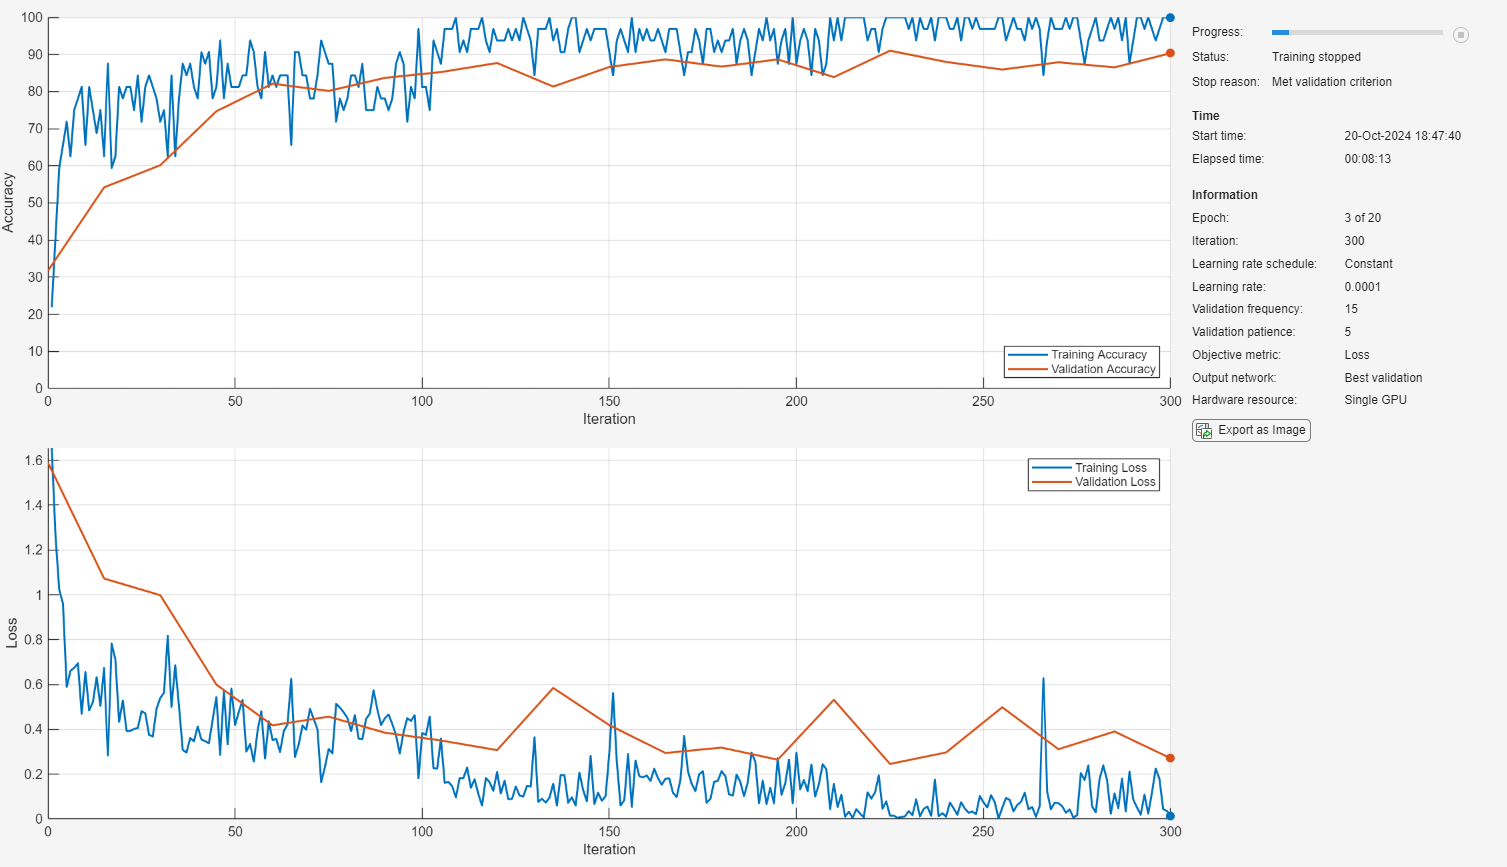

net = trainnet(augimdsTrain, net, "crossentropy", options);

## Test the network

accuracy = testnet(net,augimdsTest,"accuracy")

accuracy = 84.6755